# Explore the dynamics of a 4-dof Robotic manipulator

In this example we're going to derive and then implement the equations of motion for a 4-dof robotic manipulator. Specifically we're going to:

- Derive the equations of motion using's Lagrange's method

The system that we're going to explore is shown below.  At each joint we have:

- $\tau_m$   :     Actuation torques (eg: by electric motors)

- $b.\dot{\theta}$  :    Viscous damping torques

    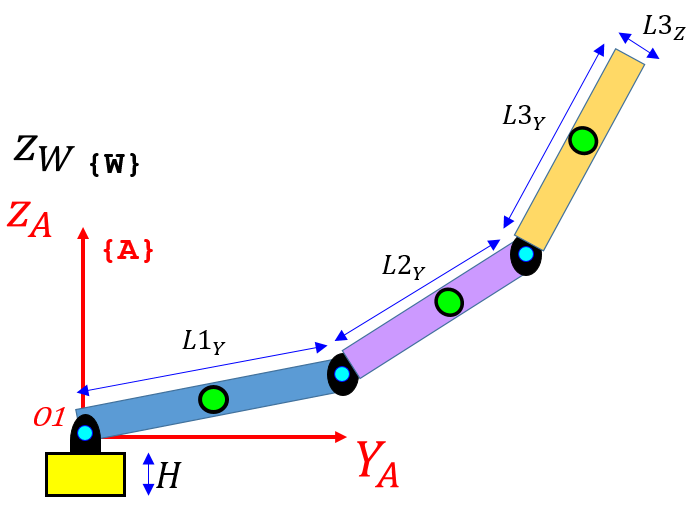   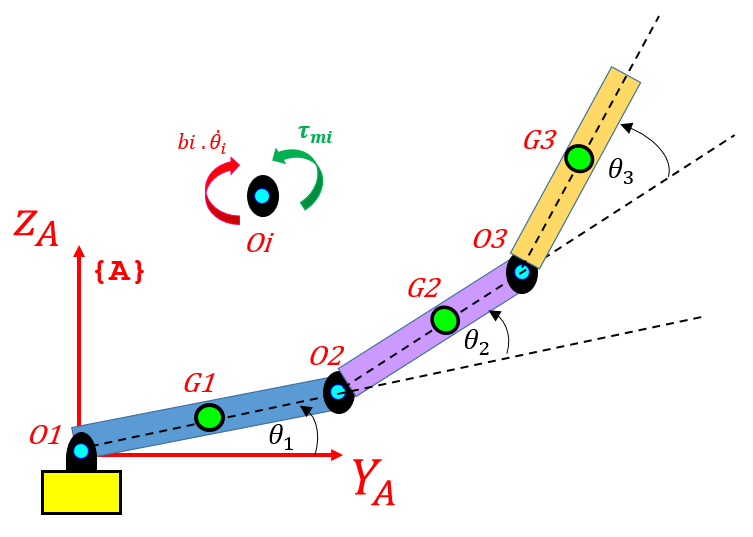   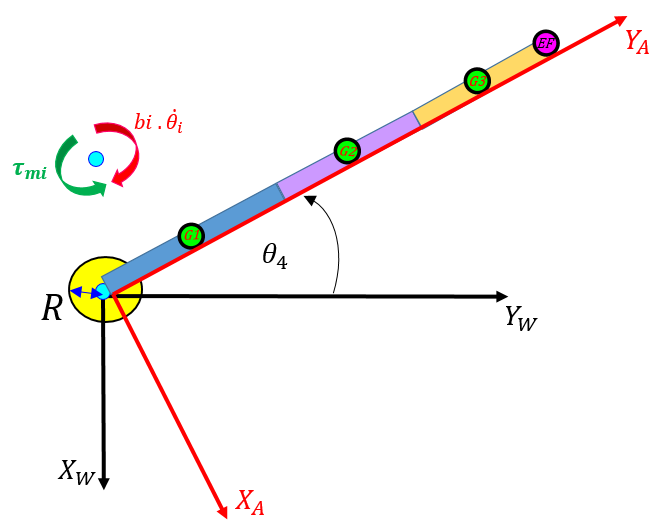         

`Bradley Horton : 13-Sep-2016, bradley.horton@mathworks.com.au`           

# **STAGE 1:** symbolic derivation of system equations

## Euler-Lagrange equations of motion:

The Euler-Lagrange formula will be used to derive the equations of motion for our robotic manipulator, and it has the form:

                           $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $     for     $k=1,2, \dots, n$

where  *n* is the DOF of the system, {$q_1, q_2, \dots, q_n$} is a set of generalized coordinates, {$Q_1, Q_2, \dots, Q_n$} is the set of generalized forces associated with those coordinates, and the Lagrangian:  ***L***** =  *****T***  ***-***  ***V****,* is defined as the difference between the kinetic and potential energy of the  *n-* DOF system. The Generalised forces can also be defined in terns of the non conservative forces and torques acting on the multibody system.  The formula for the generalised forces acting on the system is:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


where:

- $Q_k$     :    is the generalised force associated with the $k^{th}$ generalised co-ordinate $q_k$

- $Nf_{nc}$ :    is the number of active NON conservative forces

- $N\tau_{nc}$:    is the number of active NON conservative TORQUES

- $\vec{v_i}$    :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$   :    is the angular velocity about the point associated with the applied torque. 

**Note** : 

- For our system, we will choose  *q = {*$\theta_1 \thinspace, \theta_2 \thinspace, \theta_3 \thinspace, \theta_4$*}* 

- This is a 4 degree of freedom system, and as such there are four 2nd order ODEs that can be derived.

## Defining Model parameters and geometry:

           

Here are some model parameters:

syms    m2_s      m1_s       m3_s       m4_s  % masses
syms    b1_s      b2_s       b3_s       b4_s  % damping
syms taum1_s   taum2_s    taum3_s    taum4_s  % motor torques
syms     g_s                                  % gravity 

syms L1X_s L2X_s L3X_s                        % lengths for LINK #1
syms L1Z_s L2Z_s L3Z_s                        % lengths for LINK #2
syms L1Y_s L2Y_s L3Y_s                        % lengths for LINK #3
syms H4_s  R4_s                               % lengths for TURNTABLE

Here are the angles that describe the pose for our machine.  These 4 angles are also the generalised co-ordinates that we'll use with Lagrange's equation:

syms t theta1(t)  TH1_s  
syms   theta2(t)  TH2_s  
syms   theta3(t)  TH3_s  
syms   theta4(t)  TH4_s  

## Defining component INERTIAs:

The manipulator is made up of 3 rectangular prisms - which form the 3 links of the robotic "arm".  And it is also made up of a cylindrical base or "turntable".  The inertias for these fundamental shapes can be computed about a local body frame positioned at their mass centres:

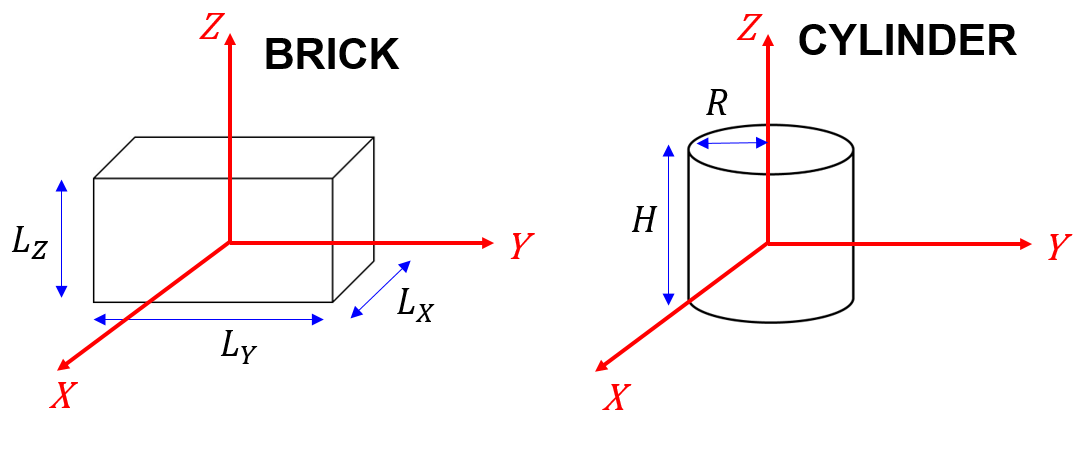

So let's define the INERTIA matrices for these components about their body fixed center of mass frames.  First let's define some formulas for the inertias of these fundamental shapes:

I_brick = @(Lx,Ly,Lz,m)...
    ( [m*(Ly^2 + Lz^2)/12,  0,                   0; ...
                        0,  m*(Lx^2 + Lz^2)/12,  0; ...
                        0,  0,                   m*(Lx^2 + Ly^2)/12;] ); 

I_cyl = @(H,R,m)...
    ( [m*(H^2 + 3*R^2)/12,  0,                   0; ...
                        0,  m*(H^2 + 3*R^2)/12,  0; ...
                        0,  0,                   m*(R^2)/2;] ); 

So the INERTIA matrices for our 4 bodies are:

I1_s = I_brick(L1X_s, L1Y_s, L1Z_s, m1_s);
I2_s = I_brick(L2X_s, L2Y_s, L2Z_s, m2_s);
I3_s = I_brick(L3X_s, L3Y_s, L3Z_s, m3_s);
I4_s = I_cyl(H4_s,  R4_s, m4_s);

## Define Center of mass positions and TRANSLATIONAL velocities for ARM links:

     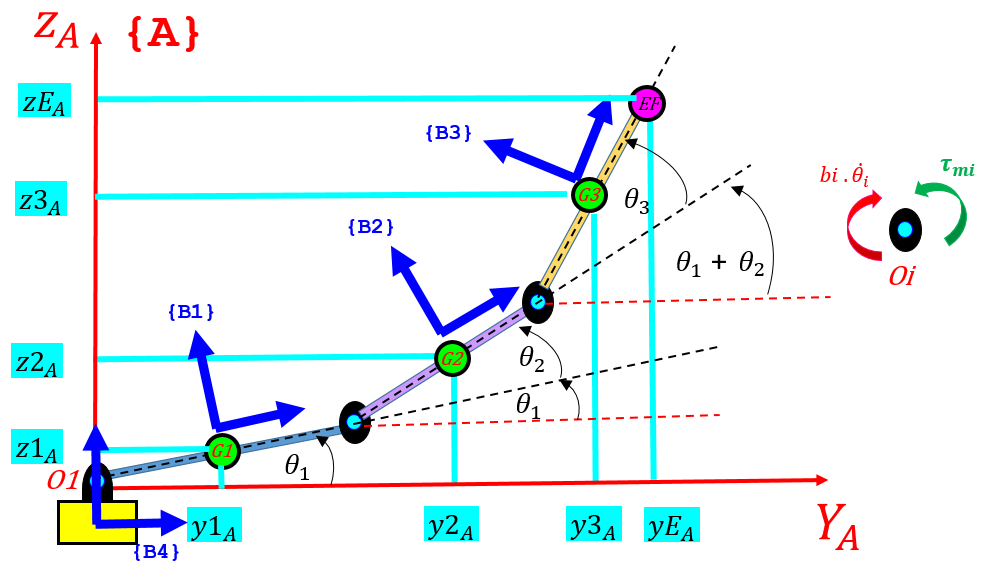     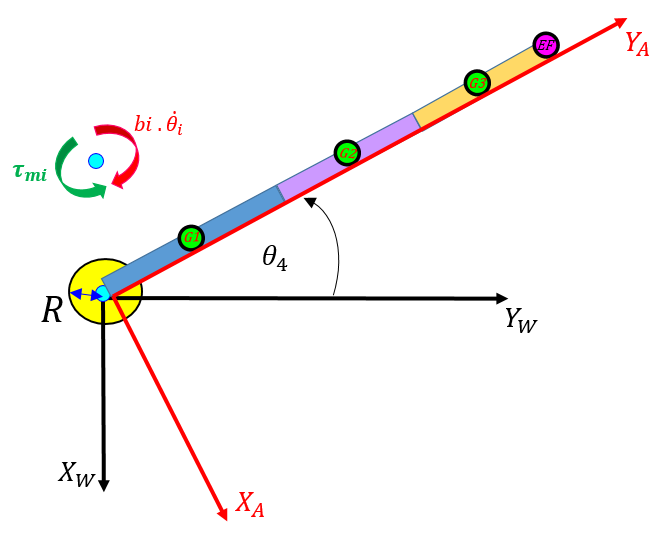    

First, let's define the x,y,z position of each link, in terms of the {A}-Frame.  And after we've done this, we'll convert the positions to our inertial {W}-frame, and then we can differentiate to get translational velocities: 

Consider LINK_1:

AF_pos_G1      = sym([0;0;0]);
AF_pos_G1(2,1) = (L1Y_s/2)*cos(theta1(t));
AF_pos_G1(3,1) = (L1Y_s/2)*sin(theta1(t));

Consider LINK_2:

alpha          = theta1(t) + theta2(t);
AF_pos_G2      = sym([0;0;0]);
AF_pos_G2(2,1) = L1Y_s*cos(theta1(t)) + (L2Y_s/2)*cos(alpha);
AF_pos_G2(3,1) = L1Y_s*sin(theta1(t)) + (L2Y_s/2)*sin(alpha);

Consider LINK_3:

beta           = theta1(t) + theta2(t) + theta3(t);
AF_pos_G3      = sym([0;0;0]);
AF_pos_G3(2,1) = L1Y_s*cos(theta1(t)) + L2Y_s*cos(alpha) + (L3Y_s/2)*cos(beta);
AF_pos_G3(3,1) = L1Y_s*sin(theta1(t)) + L2Y_s*sin(alpha) + (L3Y_s/2)*sin(beta);

We can now convert these {A}-Frame co-ordinates into their corresponding {W}-frame co-ordinates using the following transformation:

   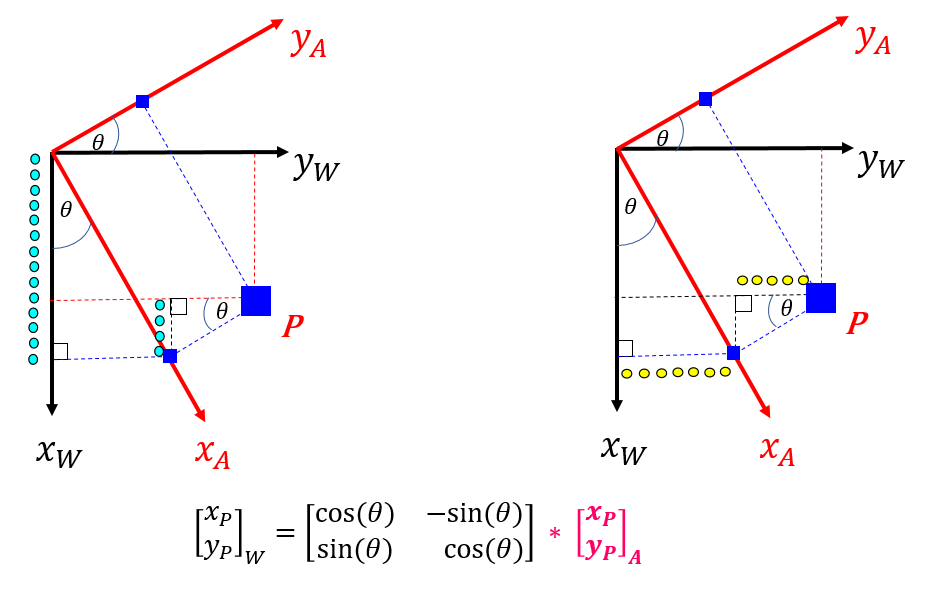

wRa = [ cos(theta4(t)),  -sin(theta4(t)),   0;
        sin(theta4(t)),   cos(theta4(t)),   0;
                     0,                0,   1 ];

So our {W}-Frame position co-ordinates are:

WF_pos_G1 = wRa * AF_pos_G1;  
WF_pos_G2 = wRa * AF_pos_G2;  
WF_pos_G3 = wRa * AF_pos_G3;                  

Now calculate our translational velocities for each link arm and express in terms of the {W}-Frame:

WF_tran_vel_G1 = diff( WF_pos_G1, t);  
WF_tran_vel_G2 = diff( WF_pos_G2, t);   
WF_tran_vel_G3 = diff( WF_pos_G3, t);  

## Define ROTATIONAL velocities for all bodies:

    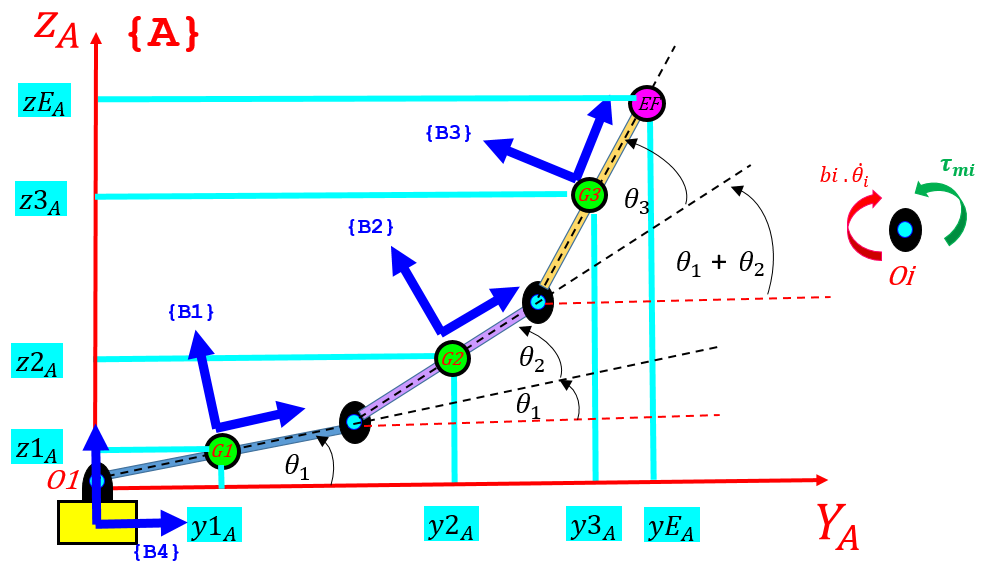        

Next we're going to define the rotational velocities for our 4 bodies. And we're going to express these rotational velocities in components of the local BODY fixed frames attached to each body - this is a natural approach because a body fixed frame means our inertias stay constant relative to that frame.  The angular velocities that we'll define are:

- $^{B1}\omega_1 :$ is the angular velocity of LINK 1, expressed in components of the {B1}-Frame

- $^{B2}\omega_2 :$ is the angular velocity of LINK 2, expressed in components of the {B2}-Frame

- $^{B3}\omega_3 :$ is the angular velocity of LINK 3, expressed in components of the {B3}-Frame

- $^{B4}\omega_4 :$ is the angular velocity of TURNTABLE, expressed in components of the {B4}-Frame

Note also, we can use the following transformation matrix, to convert an {A}-Frame vector into it's {B}-Frame components - we'll use this to convert our TURNTABLE angular velocity into components of the LINK body fixed frames:

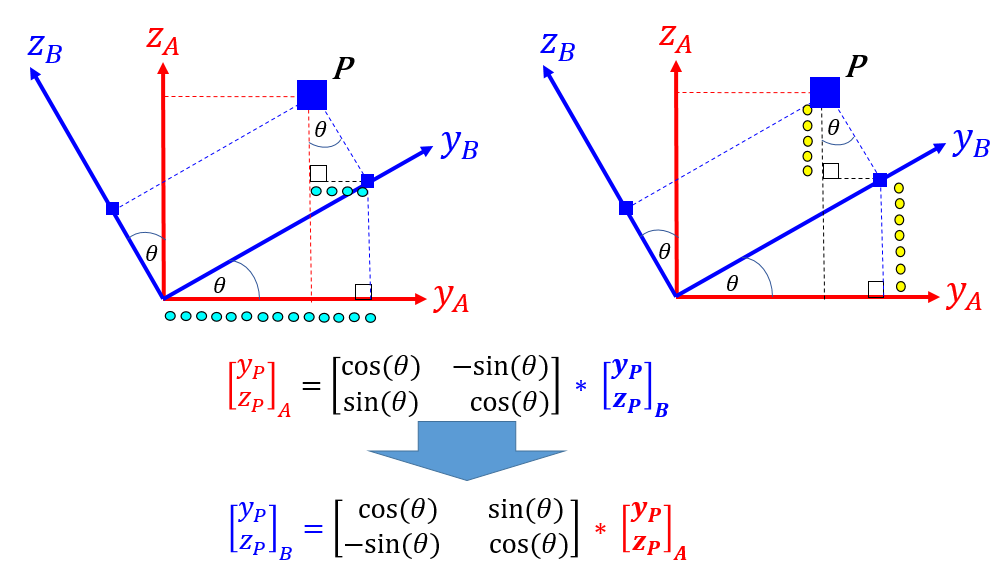

bRa = @(th) [       1,          0,         0;
                    0,    cos(th),   sin(th);
                    0,   -sin(th),   cos(th); ];

And for later, we can also go from {B-frame} to {A}-frame

aRb = @(th) [       1,          0,         0;
                    0,    cos(th),  -sin(th);
                    0,    sin(th),   cos(th); ];

OK, so let's do it.  First let's define the angular velocity of the turntable:

BF_rot_vel_B4 = [0;0; diff(theta4(t))];             

Next, let's define the angular velocity of each link in the arm.  Note that in addition to the local link rotation angles, we also have the turntable rotation angle:

AF_w = [0;0; diff(theta4(t)) ];

So our link angular velocities are:

th1           = theta1(t)                        ;
th12          = theta1(t) + theta2(t)            ;
th123         = theta1(t) + theta2(t) + theta3(t);

BF_rot_vel_B1 = bRa(th1  )*AF_w  +  [diff(th1)   ; 0; 0];
BF_rot_vel_B2 = bRa(th12 )*AF_w  +  [diff(th12)  ; 0; 0];
BF_rot_vel_B3 = bRa(th123)*AF_w  +  [diff(th123) ; 0; 0];

## Define the system KINETIC energy:

Next we'll use our previously derived expressions for body velocities and use them to define the "system" Kinetic Energy for our machine:

   

Our TRANSLATIONAL kinetic energy is:

KE_trans = 0.5*m1_s * (WF_tran_vel_G1.') *  WF_tran_vel_G1   + ...
           0.5*m2_s * (WF_tran_vel_G2.') *  WF_tran_vel_G2   + ...
           0.5*m3_s * (WF_tran_vel_G3.') *  WF_tran_vel_G3        ;

Our ROTATIONAL kinetic energy is:

KE_rot   = 0.5 * (BF_rot_vel_B1.') * I1_s *  BF_rot_vel_B1  + ...
           0.5 * (BF_rot_vel_B2.') * I2_s *  BF_rot_vel_B2  + ...
           0.5 * (BF_rot_vel_B3.') * I3_s *  BF_rot_vel_B3  + ...
           0.5 * (BF_rot_vel_B4.') * I4_s *  BF_rot_vel_B4;           

So our total kinetic energy is:

KE = KE_trans + KE_rot;      

## Define the system POTENTIAL energy:

Similarly we can define our "system" Potential Energy:

Our Potential energy is:

PE = g_s*( m1_s*WF_pos_G1(3)  + m2_s*WF_pos_G2(3)  + m3_s*WF_pos_G3(3)  );

## Define the system Lagrangian:

Next define our system Lagrangian:

L_ORIGINAL = KE - PE;

Note the symbolic variables that are inside the Lagrangian:

symvar(  L_ORIGINAL  )

$$ans = \left(\begin{array}{cccccccccccccccc} {\mathrm{L1X}}_{s} & {\mathrm{L1Y}}_{s} & {\mathrm{L1Z}}_{s} & {\mathrm{L2X}}_{s} & {\mathrm{L2Y}}_{s} & {\mathrm{L2Z}}_{s} & {\mathrm{L3X}}_{s} & {\mathrm{L3Y}}_{s} & {\mathrm{L3Z}}_{s} & R_{4,s} & g_{s} & m_{1,s} & m_{2,s} & m_{3,s} & m_{4,s} & t \end{array}\right)$$

To derive the equations of motion for our machine, "all" we need to do is a series of derivative calculations according to Lagrange's equation:

 
$$\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $$
 

## Apply Lagrange's equation:

So let's now apply Lagrange's equation:

-  $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $     for     $k=1,2, \dots, n$

First we'll define our generalised co-ordinates.  I'm going to use 2 sets of these generalised co-ordinates:

- the **ACTUAL** set of symbols are our "proper" set of symbols

- the **HOLDER** set are for easier expression manipulation

actual_list_SYM_pos = formula( [ theta1,      theta2,      theta3  ,  theta4]  );
holder_list_SYM_pos = [             TH1_s,       TH2_s        TH3_s,     TH4_s];

OK:  let's create a Lagrangian object using the class <`bh_lagr4manips_CLS`>

lag_OBJ = bh_lagr4manips_CLS( KE, PE, actual_list_SYM_pos, holder_list_SYM_pos);

And let's compute the system's equations of motion:

lag_OBJ = lag_OBJ.calc_eom()

lag_OBJ =   bh_lagr4manips_CLS with properties:

                   T_KE: [1×1 sym]
                   V_PE: [1×1 sym]
                      L: [1×1 sym]
                Qk_list: [4×1 sym]
                    EOM: [1×4 bh_eom_CLS]
                  N_dof: 4
    actual_list_SYM_pos: [4×1 sym]
    actual_list_SYM_vel: [4×1 sym]
    actual_list_SYM_acc: [4×1 sym]
    holder_list_SYM_pos: [4×1 sym]
    holder_list_SYM_vel: [4×1 sym]
    holder_list_SYM_acc: [4×1 sym]


So what do the equations of motion actually look like ? - they are long equations involving many terms

lag_OBJ.show_eom()


#######################################################
### q = theta1(t)
### 
### LHS of EOM is: 
### 
        (L1Y_s^2*m1_s*diff(theta1(t), t, t))/3 + L1Y_s^2*m2_s*diff(theta1(t), t, t) + L1Y_s^2*m3_s*diff(theta1(t), t, t) + (L2Y_s^2*m2_s*diff(theta1(t), t, t))/3 + (L2Y_s^2*m2_s*diff(theta2(t), t, t))/3 + L2Y_s^2*m3_s*diff(theta1(t), t, t) + L2Y_s^2*m3_s*diff(theta2(t), t, t) + (L3Y_s^2*m3_s*diff(theta1(t), t, t))/3 + (L3Y_s^2*m3_s*diff(theta2(t), t, t))/3 + (L3Y_s^2*m3_s*diff(theta3(t), t, t))/3 + (L1Z_s^2*m1_s*diff(theta1(t), t, t))/12 + (L2Z_s^2*m2_s*diff(theta1(t), t, t))/12 + (L2Z_s^2*m2_s*diff(theta2(t), t, t))/12 + (L3Z_s^2*m3_s*diff(theta1(t), t, t))/12 + (L3Z_s^2*m3_s*diff(theta2(t), t, t))/12 + (L3Z_s^2*m3_s*diff(theta3(t), t, t))/12 + (L2Y_s*g_s*m2_s*cos(theta1(t) + theta2(t)))/2 + L2Y_s*g_s*m3_s*cos(theta1(t) + theta2(t)) + (L3Y_s^2*m3_s*sin(2*theta1(t) + 2*theta2(t) + 2*theta3(t))*diff(theta4(t), t)^2)/6 - (L3Z_s^2*m3_s*sin(2*theta1(t) + 2*theta2(t) + 2*theta3(t))*diff(

# **Define the Generalised forces:**

Next we need to calculate our Generalised forces.  Recall the formula for the generalised forces acting on the system:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


where:

- $Q_k$     :    is the generalised force associated with the $k^{th}$ generalised co-ordinate $q_k$

- $Nf_{nc}$ :    is the number of active NON conservative forces

- $N\tau_{nc}$:    is the number of active NON conservative TORQUES

- $\vec{v_i}$    :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$   :    is the angular velocity about the point associated with the applied torque. 

Define some angular velocities:

th1dot     = formula( diff(theta1, t)  );
th2dot     = formula( diff(theta2, t)  );
th3dot     = formula( diff(theta3, t)  );
th4dot     = formula( diff(theta4, t)  );

I'm going to define a matrix, whos columns represent the vectors of the NON conservative torques for LINK 1, and another matrix whose columns represent the angular velocities associated with these torques:

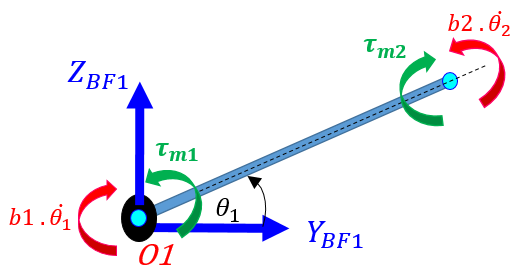

the_tau_mat_LINK_1 = [ ...
       (taum1_s),   (-b1_s*th1dot),   (-taum2_s),      (b2_s*th2dot); 
               0,                0,            0,                  0;          
               0,                0,            0,                  0;    ]; 
       
the_w_mat_LINK_1 = [ ...
    BF_rot_vel_B1,    BF_rot_vel_B1,   BF_rot_vel_B1,    BF_rot_vel_B1 ];

And similarly for LINK 2:

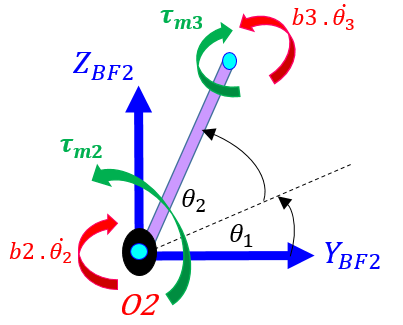

the_tau_mat_LINK_2 = [ ...
       (taum2_s),   (-b2_s*th2dot),   (-taum3_s),     (b3_s*th3dot);    
               0,                0,            0,                  0;          
               0,                0,            0,                  0;  ];        
   
the_w_mat_LINK_2 = [ ...
    BF_rot_vel_B2,    BF_rot_vel_B2,   BF_rot_vel_B2,    BF_rot_vel_B2 ];

And similarly for LINK 3:

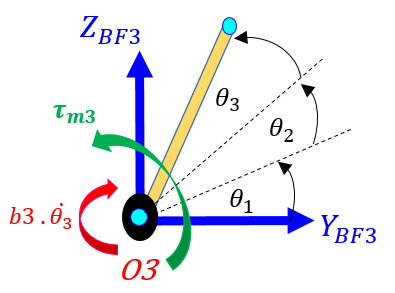

the_tau_mat_LINK_3 = [ ...
     (taum3_s),     (-b3_s*th3dot)            
             0,                  0;          
             0,                  0;  ];

the_w_mat_LINK_3 = [ ...
     BF_rot_vel_B3,         BF_rot_vel_B3 ];

And similarly for the turntable:

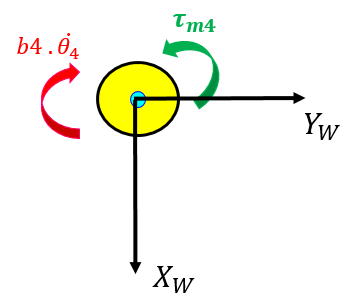

the_tau_mat_LINK_4 = ...
   [         0,                  0;          
             0,                  0;          
     (taum4_s),     (-b4_s*th4dot)   ];

the_w_mat_LINK_4 = [ ...
    BF_rot_vel_B4,         BF_rot_vel_B4 ];     

So concatenate these into single matrices:

the_tau_mat_actual = [the_tau_mat_LINK_1, the_tau_mat_LINK_2, the_tau_mat_LINK_3,  the_tau_mat_LINK_4];
the_w_mat_actual   = [  the_w_mat_LINK_1,   the_w_mat_LINK_2,   the_w_mat_LINK_3,    the_w_mat_LINK_4];

Now let's compute $Q_k$:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


To do this we'll create a generalised force object using the class <`bh_genF4manips_CLS`>

genF_OBJ = bh_genF4manips_CLS( the_tau_mat_actual, ...
                               the_w_mat_actual, ...
                               actual_list_SYM_pos, ...
                               holder_list_SYM_pos);

And now calculate our system's generalised forces:                          

genF_OBJ = genF_OBJ.calc_genF();

What do the $Q_k's$ look like?

genF_OBJ.show_genF_holder()


#######################################################
### q = TH1_s
### 
### Qk (HOLDER) is: 
### 
      taum1_s - TH1_s_D*b1_s
#######################################################
### q = TH2_s
### 
### Qk (HOLDER) is: 
### 
      taum2_s - TH2_s_D*b2_s
#######################################################
### q = TH3_s
### 
### Qk (HOLDER) is: 
### 
      taum3_s - TH3_s_D*b3_s
#######################################################
### q = TH4_s
### 
### Qk (HOLDER) is: 
### 
      taum4_s - TH4_s_D*b4_s

Or we can retrieve all of the $Q_k's$ as a vector:

the_Qk_vec = genF_OBJ.get_Qk('all', 'holder')

$$the\_Qk\_vec = \left(\begin{array}{c} {\mathrm{taum}}_{1,s}-{\mathrm{TH}}_{1,s,D}\,b_{1,s}\\ {\mathrm{taum}}_{2,s}-{\mathrm{TH}}_{2,s,D}\,b_{2,s}\\ {\mathrm{taum}}_{3,s}-{\mathrm{TH}}_{3,s,D}\,b_{3,s}\\ {\mathrm{taum}}_{4,s}-{\mathrm{TH}}_{4,s,D}\,b_{4,s} \end{array}\right)$$

## Absorb the Generalised Forces:

We can insert these Generalised forces into the "Lagrangian" object that we created earlier, and then recalculate the equations of motion:

lag_OBJ = lag_OBJ.calc_eom(genF_OBJ);

 Now echo our equations:

lag_OBJ.get_eom( 1:4, 'holder', 'RHS')

$$ans = \left(\begin{array}{c} {\mathrm{taum}}_{1,s}-{\mathrm{TH}}_{1,s,D}\,b_{1,s}\\ {\mathrm{taum}}_{2,s}-{\mathrm{TH}}_{2,s,D}\,b_{2,s}\\ {\mathrm{taum}}_{3,s}-{\mathrm{TH}}_{3,s,D}\,b_{3,s}\\ {\mathrm{taum}}_{4,s}-{\mathrm{TH}}_{4,s,D}\,b_{4,s} \end{array}\right)$$

## Now let's get the M,C,K,G,Q matrices:

We can express our system equations of motion in the following form:


$$M(q).\ddot{q} \enspace + \enspace
C(q,\dot{q}).\dot{q} \enspace + \enspace
K(q).q \enspace + \enspace
 g(q) = Q$$


 lag_OBJ = lag_OBJ.create_MCKGQ();

Retrieve the MCKGQ struct:

res_T = lag_OBJ.get_MCKGQ()

res_T =   bh_MCKGQ_CLS with properties:

           M: [4×4 sym]
           C: [4×4 sym]
           K: [4×4 sym]
           G: [4×1 sym]
           Q: [4×1 sym]
     ACC_col: [4×1 sym]
     VEL_col: [4×1 sym]
     POS_col: [4×1 sym]
    acc_eoms: [4×1 sym]


And let's have a look at each of these terms:

Here's **M**:

res_T.M

Here's **C**:

res_T.C

Here's **K**:

res_T.K

$$ans = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

Here's **G**:

res_T.G

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{g_{s}\,\left({\mathrm{L2Y}}_{s}\,m_{2,s}\,\cos\left({\mathrm{TH}}_{1,s}+{\mathrm{TH}}_{2,s}\right)+2\,{\mathrm{L2Y}}_{s}\,m_{3,s}\,\cos\left({\mathrm{TH}}_{1,s}+{\mathrm{TH}}_{2,s}\right)+{\mathrm{L1Y}}_{s}\,m_{1,s}\,\cos\left({\mathrm{TH}}_{1,s}\right)+2\,{\mathrm{L1Y}}_{s}\,m_{2,s}\,\cos\left({\mathrm{TH}}_{1,s}\right)+2\,{\mathrm{L1Y}}_{s}\,m_{3,s}\,\cos\left({\mathrm{TH}}_{1,s}\right)+{\mathrm{L3Y}}_{s}\,m_{3,s}\,\sigma_{2}\right)}{2}\\ \sigma_{1}+\frac{{\mathrm{L2Y}}_{s}\,g_{s}\,m_{2,s}\,\cos\left({\mathrm{TH}}_{1,s}+{\mathrm{TH}}_{2,s}\right)}{2}+{\mathrm{L2Y}}_{s}\,g_{s}\,m_{3,s}\,\cos\left({\mathrm{TH}}_{1,s}+{\mathrm{TH}}_{2,s}\right)\\ \sigma_{1}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{L3Y}}_{s}\,g_{s}\,m_{3,s}\,\sigma_{2}}{2}\\ \sigma_{2}=\cos\left({\mathrm{TH}}_{1,s}+{\mathrm{TH}}_{2,s}+{\mathrm{TH}}_{3,s}\right) \end{array}$$

Here's **Q**:

res_T.Q

$$ans = \left(\begin{array}{c} {\mathrm{taum}}_{1,s}-{\mathrm{TH}}_{1,s,D}\,b_{1,s}\\ {\mathrm{taum}}_{2,s}-{\mathrm{TH}}_{2,s,D}\,b_{2,s}\\ {\mathrm{taum}}_{3,s}-{\mathrm{TH}}_{3,s,D}\,b_{3,s}\\ {\mathrm{taum}}_{4,s}-{\mathrm{TH}}_{4,s,D}\,b_{4,s} \end{array}\right)$$

## Now create the MATLAB function blocks for Simulink:

To use/solve these derived equations of motion we'll create a MATLAB Function block that can be usde inside Simulink:

lag_OBJ.create_MLF_blocks()

Evaluating callback 'PostLoadFcn' for simulink
Callback: setsysloc_simulink(bdroot)
Evaluating callback 'LoadFcn' for simulink/Sources/Waveform Generator
Callback: set_param(gcb,'LoadFlag','1');


Evaluating callback 'LoadFcn' for simulink/Sources/Signal Builder
Callback: sigbuilder_block('load');
Evaluating callback 'LoadFcn' for simulink/Sinks/XY Graph
Callback: sfunxy([],[],[],'LoadBlock')
Evaluating callback 'LoadFcn' for simulink/Model-Wide Utilities/Model Info
Callback: slcm LoadBlock;
Evaluating callback 'LoadFcn' for simulink/Math Operations/Slider Gain
Callback: slideg Load
